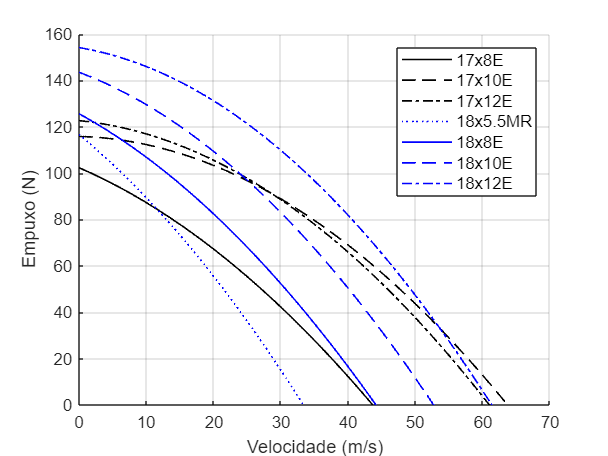

% Criar o vetor X
X = linspace(0, 75, 750);

% Definir as funções
T17x8E = @(X) -0.0249.*X.^2 - 1.2568.*X + 102.3320;
T17x10E = @(X) -0.0273.*X.^2 - 0.07934.*X + 115.8218;
T17x12E = @(X) -0.0282.*X.^2 - 0.2911.*X + 122.6452;
T18x55MR = @(X) -0.0332.*X.^2 - 2.3898.*X + 116.6083;
T18x8E = @(X) -0.0284.*X.^2 - 1.5923.*X + 125.6174;
T18x10E = @(X) -0.0311.*X.^2 - 1.0840.*X + 143.4866;
T18x12E = @(X) -0.0330.*X.^2 - 0.4877.*X + 154.1342;

% Plotar os gráficos
figure;
hold on;

plot(X, T17x8E(X), 'k-', 'LineWidth', 1, 'DisplayName', '17x8E');
plot(X, T17x10E(X), 'k--', 'LineWidth', 1, 'DisplayName', '17x10E');
plot(X, T17x12E(X), 'k-.', 'LineWidth', 1, 'DisplayName', '17x12E');
plot(X, T18x55MR(X), 'b:', 'LineWidth', 1, 'DisplayName', '18x5.5MR');
plot(X, T18x8E(X), 'b-', 'LineWidth', 1, 'DisplayName', '18x8E');
plot(X, T18x10E(X), 'b--', 'LineWidth', 1, 'DisplayName', '18x10E');
plot(X, T18x12E(X), 'b-.', 'LineWidth', 1, 'DisplayName', '18x12E');

% Configurar o gráfico
xlabel('Velocidade (m/s)');
ylabel('Empuxo (N)');

axis([0, 70, 0, 160]);
grid on;
legend('Location', 'northeast', 'FontSize', 10);
hold off;

set(gcf,'PaperPositionMode','auto')
print('Figura20','-dpng','-r450')